close all; clear; clc;

# 90% increments of 10 data test

**filename**: PercentInc10_20180628.mlx

**keywords:** acceleration tests

**file created by:** {20180629, Edmonds}

**last updated on:** {20180701}

**primary purpose:** This test records the max acceleration and 'settling time' after increasing the throttle setting in the desired increments. EXPERIMENTAL SCRIPT. Shouldn't be used as verified data

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** [C_T], [C_P], [C_Q]

**Notes:** Rotational Speed was calculated in RPM, need to convert to rad/sec

Don't think I tore the load cell or voltage before running tests

Didn't have data being collected the entire time, so there are only 11 data points for each column. Can set it to a setting where all data will be continuously collected, which I think is the way this test should be ran.

**Neet to run another test in 10% increments where all data is being collected to compare data sets.**

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
p = 0.002285947263;                  %[slugs/ft^3]

% Motor Specs
radius = 7.5/12;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data

This format assumes that the "servo" column was deleted beforehand

load('Percent_inc10.mat');
time = Percent_inc10(:,1);          % [sec]
ESC_us = Percent_inc10(:,2);        % [micro sec] (this is how quickly the ESC is providing voltage to the motor -- translates to throttle% ?
Q = Percent_inc10(:,3);             % [ft.lbf]
T = Percent_inc10(:,4);             % [lbf]
Input_V = Percent_inc10(:,5);       % [Volts]
Input_A = Percent_inc10(:,6);       % [Amps]
rot_speed_RPM = Percent_inc10(:,7);     % [rad/sec]
%Convert RPM to rad/sec
rot_speed = rot_speed_RPM .* (pi/30);

P_in_W = Percent_inc10(:,8);        % [Watts]
P_out_W = Percent_inc10(:,9);        % [Watts]

% convert to [ft.lbf/sec]
P_out = P_out_W .* 0.7478;     % [ft.lbf/sec]         
P_in = P_in_W .* 0.7478;       % [ft.lbf/sec]

Motor_Eff = Percent_inc10(:,10);    % [%]
Prop_Eff = Percent_inc10(:,11);     % [lbf/Watts]
Overall_Eff = Percent_inc10(:,12);  % [lbf/Watts]  
Motor_Temp = Percent_inc10(:,13);   % [F]

Settling_time = Percent_inc10(:,14); % [s]
Max_Acc = Percent_inc10(:,15);      % [RPM]


## Disk Loading

D_L = T ./ area;

## Thrust, Power, and Torque Coefficents

[C_T] = Thrust_Coefficient(T,p,area,rot_speed,radius);
[C_P] = Power_Coefficient(P_out,p,area,rot_speed,radius);
[C_Q] = Torque_Coefficient(Q,p,area,rot_speed,radius);

## Plots

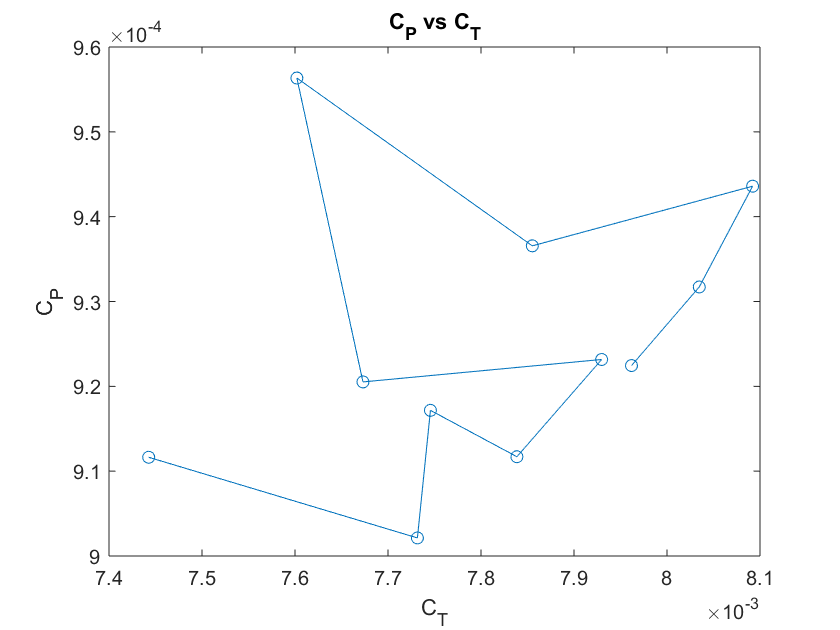

figure(1)
plot(C_T, C_P,'o-');
title('C_P vs C_T'); xlabel('C_T'); ylabel('C_P')

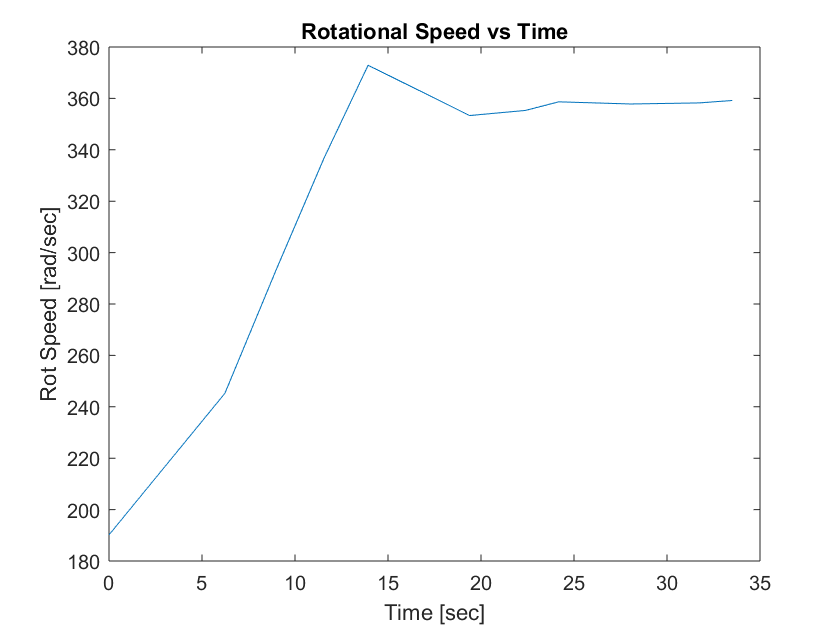

figure(2)
plot(time, rot_speed); title('Rotational Speed vs Time');
xlabel('Time [sec]'); ylabel('Rot Speed [rad/sec]')

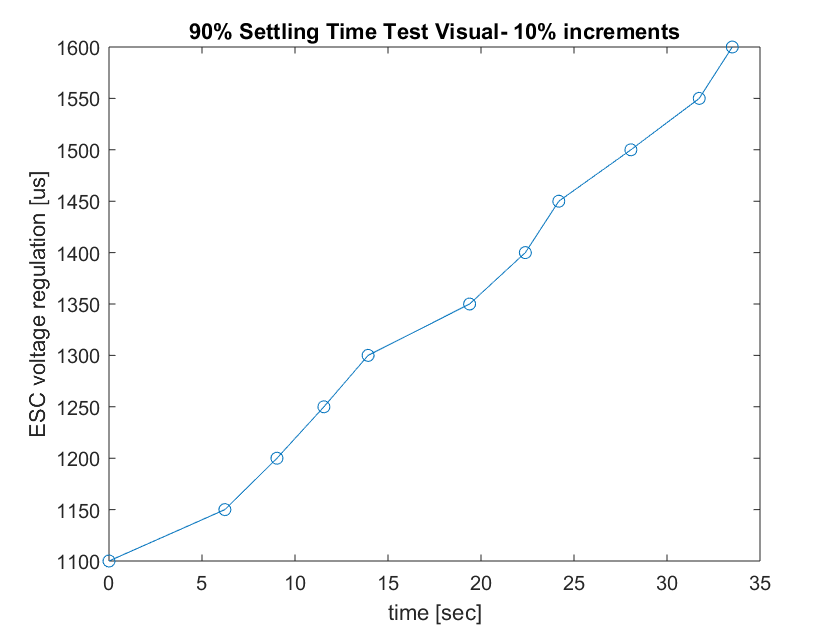

figure(3)
plot(time, ESC_us, 'o-'); title('90% Settling Time Test Visual- 10% increments'); 
xlabel('time [sec]'); ylabel('ESC voltage regulation [us]');

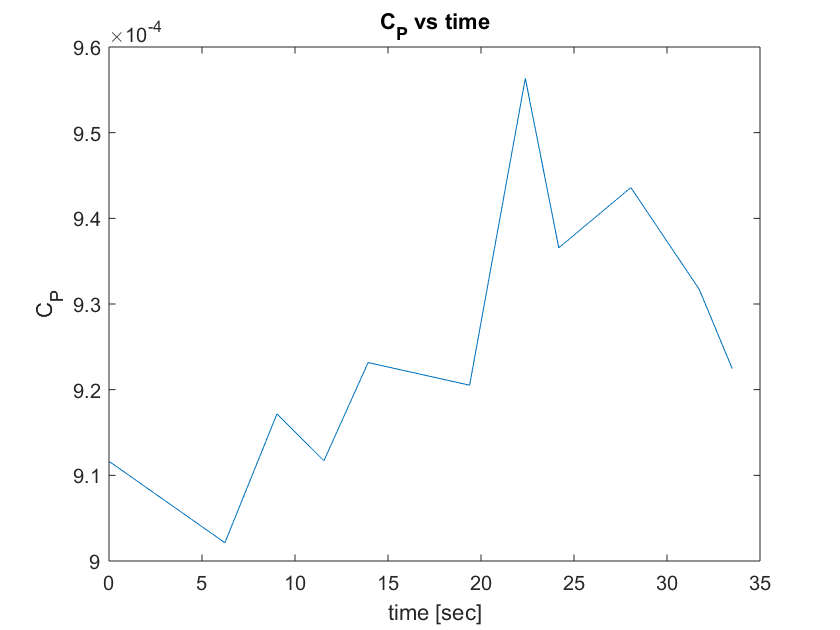

figure(4)
plot(time, C_P); title('C_P vs time');
xlabel('time [sec]'); ylabel('C_P'); 

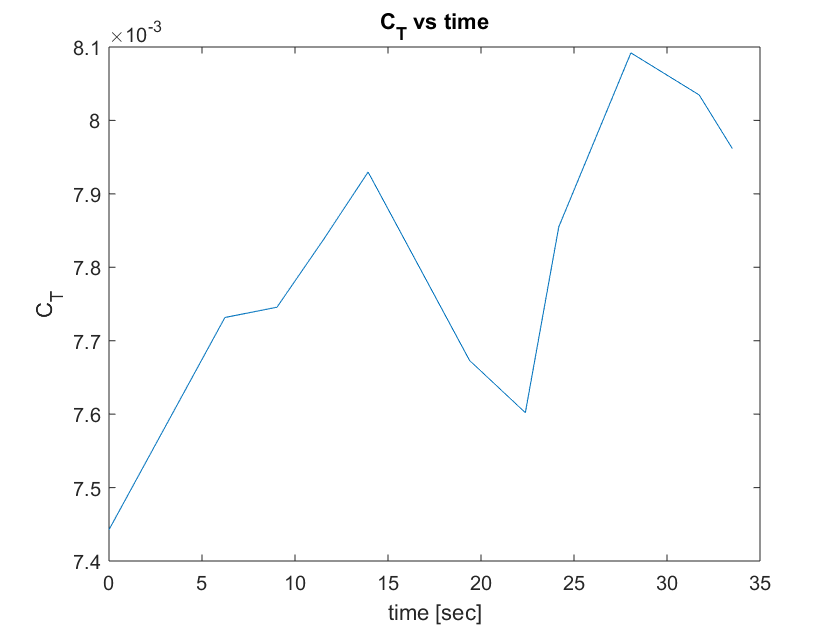

figure(5)
plot(time, C_T); title('C_T vs time');
xlabel('time [sec]'); ylabel('C_T'); 

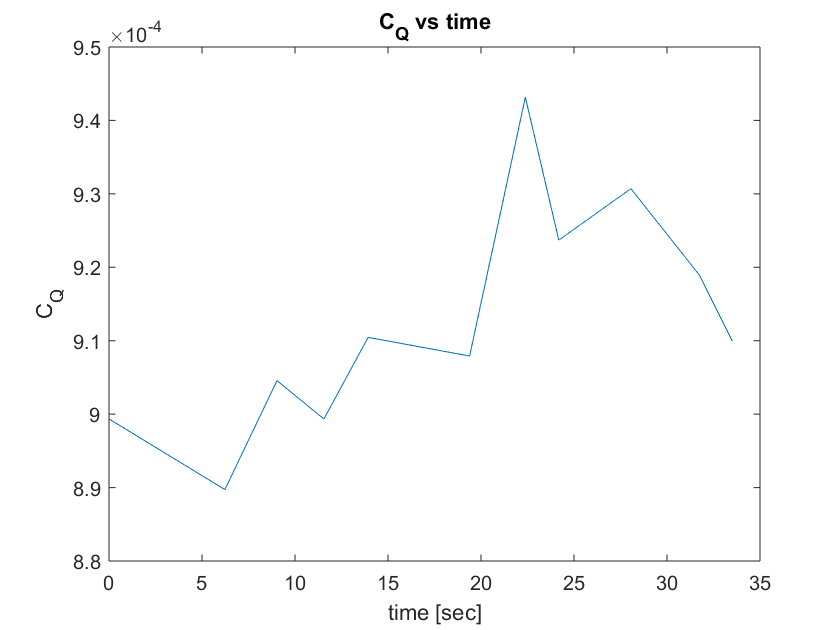

figure(6)
plot(time, C_Q); title('C_Q vs time');
xlabel('time [sec]'); ylabel('C_Q'); 

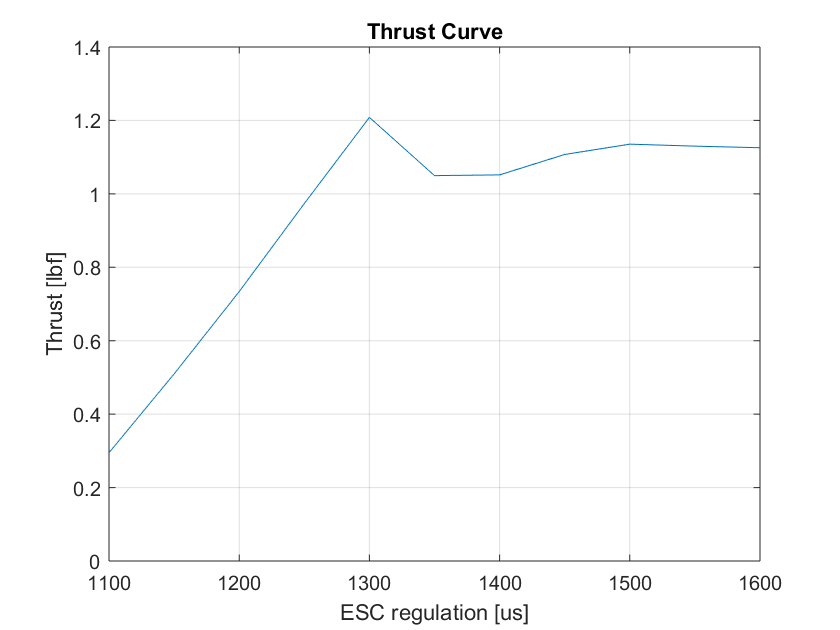

figure(7)
plot(ESC_us, T);title('Thrust Curve'); 
xlabel('ESC regulation [us]'); ylabel('Thrust [lbf]'); 
grid('on'); ylim([0,1.4]);

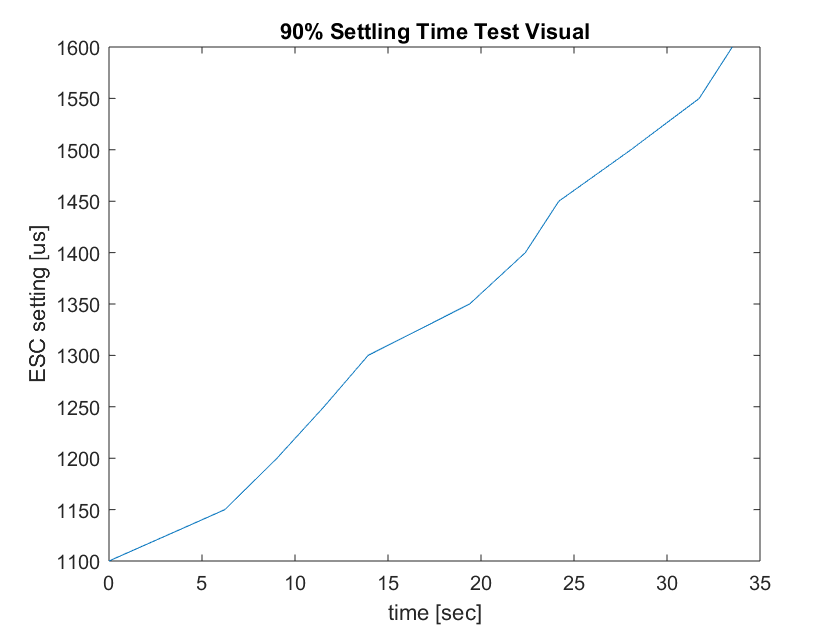

figure(8)
plot(time, ESC_us); title('90% Settling Time Test Visual');
xlabel('time [sec]'); ylabel('ESC setting [us]')

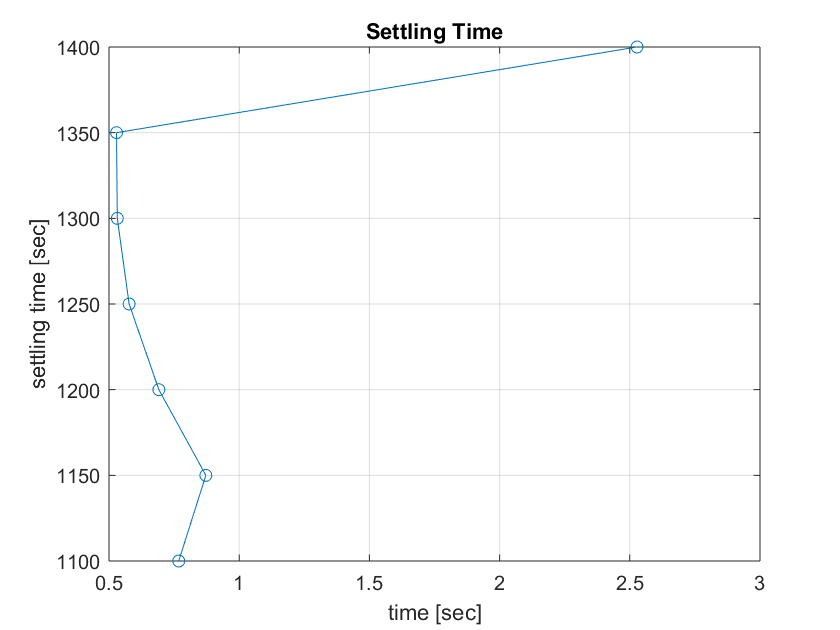

figure(9)
plot(Settling_time, ESC_us, 'o-'); title('Settling Time');
xlabel('time [sec]'); ylabel('settling time [sec]'); grid('on');

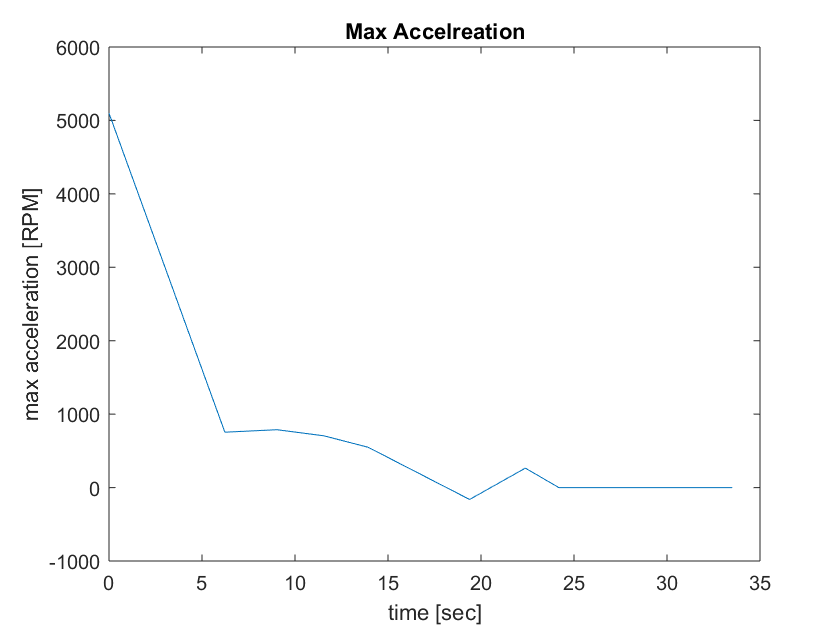

figure(10)
plot(time, Max_Acc); title('Max Accelreation')
xlabel('time [sec]'); ylabel('max acceleration [RPM]')

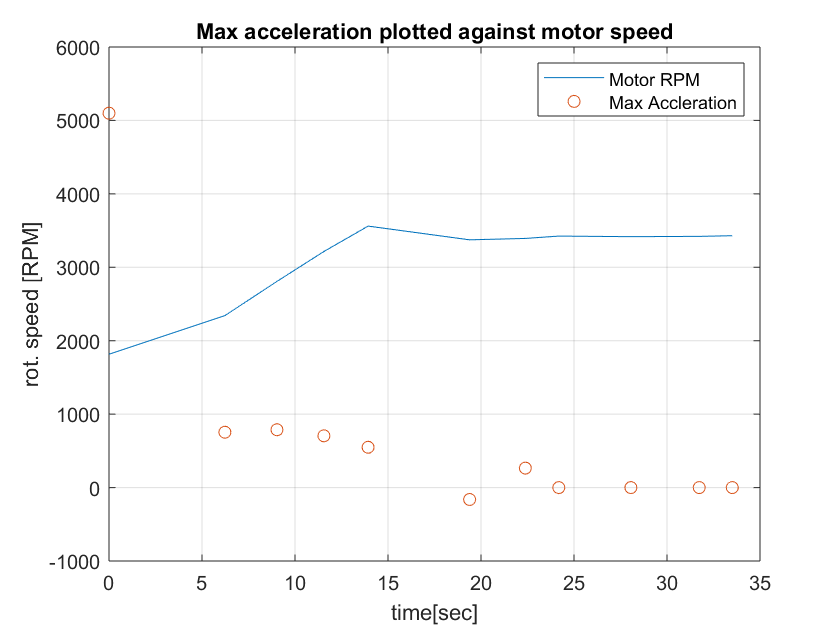

figure(11)
plot(time, rot_speed_RPM, time, Max_Acc, 'o');
title('Max acceleration plotted against motor speed')
xlabel('time[sec]'); ylabel('rot. speed [RPM]'); 
legend('Motor RPM', 'Max Accleration'); grid('on');

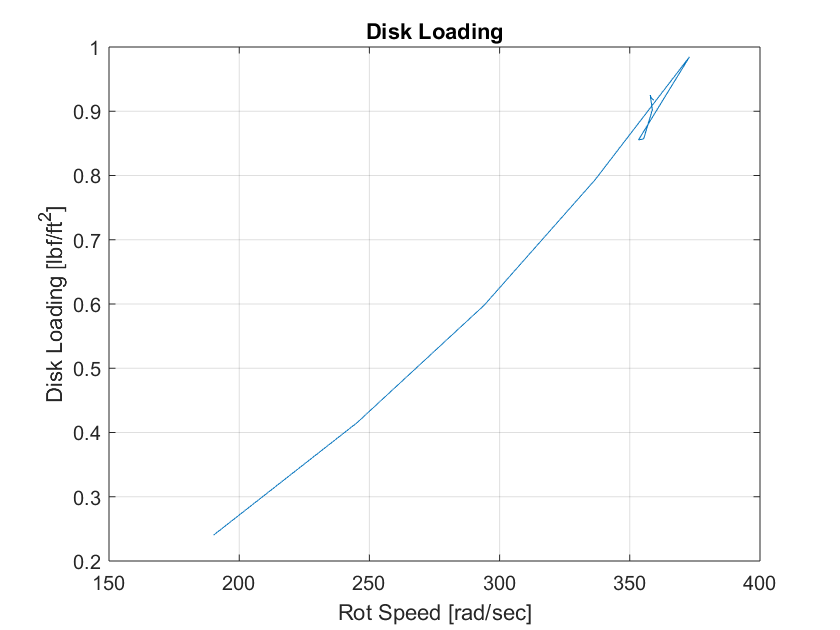

figure(12)
plot(rot_speed, D_L)
xlabel('Rot Speed [rad/sec]'); ylabel('Disk Loading [lbf/ft^2]'); 
title('Disk Loading'); grid('on');

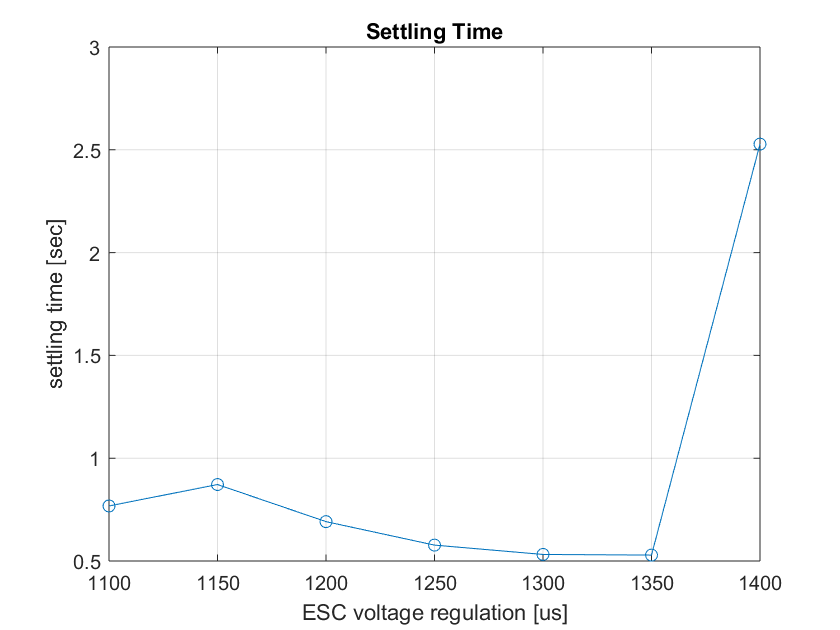

figure(13)
plot(ESC_us, Settling_time, 'o-'); title('Settling Time');
xlabel('ESC voltage regulation [us]'); ylabel('settling time [sec]'); grid('on');